3. Write a computer program to carry out the Monte Carlo Random Walk solution method for following BVP

PDE            $u_{\mathrm{xx}} +u_{\mathrm{yy}} =0$        $0<x<1$,$0<y<1$

BCs            $u\left(0,y\right)=0$            $0<y<1$

                    
$$u\left(1,y\right)=2y$$
            
$$0<y<1$$


                    
$$u\left(x,0\right)=0$$
            
$$0<x<1$$


                    
$$u\left(x,1\right)=1$$
            
$$0<x<1$$


You may use a uniform grid size h=k or let the x grid size (h) and y grid size (k) be diffierent. How accurate  is  your  solution? How do you know? Also, code the problem using the Finite Difference method. Compare your solution to that from MC. Discuss.

By using  Monte Carlo Random Walk method we need to calculate the probability that random walk attach to the boundary which starts from each point inside the boundary.

So for each point A and each boundary point $p_k$ $P_A \left(p_k \right)=\frac{\mathrm{Number}\;\mathrm{of}\;\mathrm{times}\;\mathrm{reached}\;p_k \;\mathrm{from}\;A}{\mathrm{Total}\;\mathrm{number}\;\mathrm{of}\;\mathrm{random}\;\mathrm{walk}}$        (1)

And compute the each interior point by adding the 'expectation value' together:

$u\left(A\right)=\sum_k g_k P_A \left(p_k \right)$            (2)

Where $g_k$ is the boundary condition.

Then in order to do the random walk since x and y has same grid, the probability that the walks goes to each way are the same. So we will generate a random number with $w~U\left(0,1\right)$ and

If $0\le w<0\ldotp 25$    move from (i,j) to (i+1,j), which is North direction

If $0\ldotp 25\le w<0\ldotp 5$move from (i,j) to (i-1,j), which is Sorth direction

If $0\ldotp 5\le w<0\ldotp 75$move from (i,j) to (i,j+1), which is East direction

If $0\ldotp 75\le w<1$    move from (i,j) to (i,j-1), which is West direction

The specific step is:

Step 0:  Choose a finite number of simulations to run (i.e. random walks to complete). Call this number "numWalks".  Initialize all necessary components. 

(LOOP) For n=1,2,3,... total number of interior points do the following

    Step 1:  Choose an interior point  (i,j) (for which the solution u(x_j,y_i) is still unknown).  Let's call it A=(i,j)

for the time being. Initialize COUNTER=0.

        Step 2a: Generate a random number w in [0,1] from the uniform distribution. Then start walking by following the method state above.

        Step 2b: For each walk test if it attach the boundary. If not, repeat Step 2a. If so, stop the walk and record the boundary point you ended up at.

        Step 3. Return to your chosen interior point A and repeat Step 2 until you have reached the total

number of walks to complete "numWalks".

        Step 4: For your chosen interior point A, compute the fraction $P_A \left(p_k \right)$ 

        Step 5: Compute the approximate solution at the chosen interior point $u\left(A\right)=\sum_k g_k P_A \left(p_k \right)$

   Step 6: Repeat Steps 1-5 for the remaining interior points.

End loop.

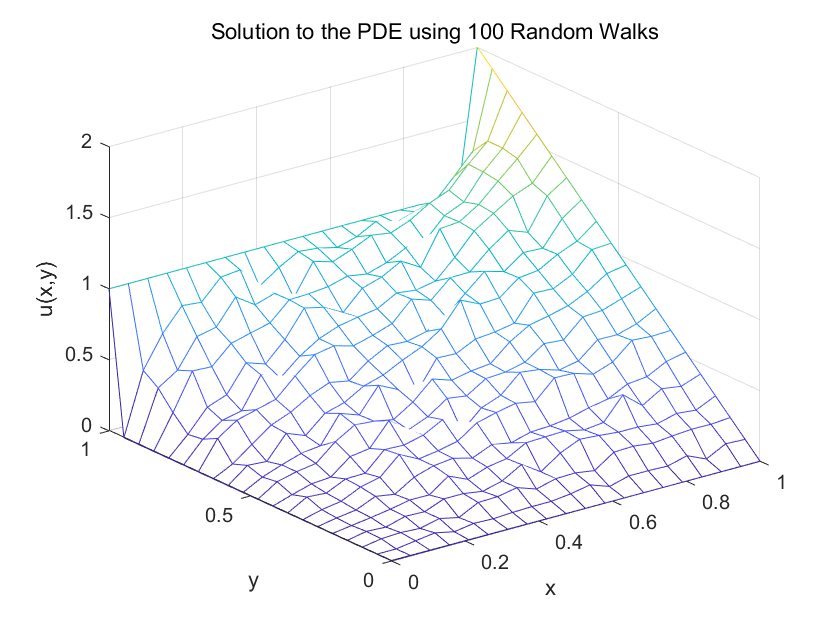

clear
% Step 0:

% Inputs
numWalks     = 100;%set numWaks
numPts       = 20; % number of discretization points in each direction on the board.

% Discretization 
h            = (1-0)/(numPts-1);
x            = 0:h:1;
y            = 0:h:1;

% Set up the entire grid:
[xx,yy]      = meshgrid(x,y);

% Initialize:
u_sol        = zeros(size(xx));


% Enforce the BC u(x,1)=1;
u_sol(end,:) = 1; %BC, If y=1, the value of u(x,y)=1.
u_sol(:,end) = 2*y;%BC, u(1,y)=2y
u        = u_sol;
% Determine how many boundary points there are (not counting the corners of the board)
numBndry     = 4*(numPts-2);

% Loop over all of the interior points
for ii = 2:(numPts-1)    
    for jj = 2:(numPts-1)
        % Initialize counter for the given point 
        % to track how many walks end up at each boundary point.
        counter = zeros(size(xx)); 

        for nn = 1:numWalks % Walks loop            
            % Step 1: Choose point A=(ii,jj)
            xPt = jj;
            yPt = ii;
            
            % Step 2: 
            while xPt~=1 && xPt~=numPts && yPt~=1 && yPt~=numPts 
                % Step 2b test if the walk attach to the boundary point
                w = rand; 
                % Step 2a generate w~U(0,1)
                % WALK
                if w>=0 && w<0.25
                    yPt = yPt + 1; % walk north
                elseif w>=0.25 && w<0.50
                    yPt = yPt - 1; % walk south
                elseif w>=.5 && w<0.75
                    xPt = xPt + 1; % walk east
                elseif w>=0.75 && w<=1
                    xPt = xPt - 1; % walk west
                end
            end 
            
            % Once the walk attach the boundary, Record number
            counter(yPt,xPt) = counter(yPt,xPt) + 1;
            % Step 4 compute the fraction
            counter_frac = counter/numWalks; 
        
            % Step 5: Compute the approximate solution at the point A=(ii,jj)      
            u(ii,jj)=sum(u_sol.*counter_frac,'all');
        end 
    end
end   

%plot
mesh(xx,yy,u);
xlabel('x'); ylabel('y');zlabel('u(x,y)')
title(['Solution to the PDE using ' num2str(numWalks) ' Random Walks'])

From the plot above we could see that, the surface is rough due to the method and number of random walk we use. with low number of random walk it will be hard to an accurate surface and solution we want.

Then using Finite Difference method

The method is same as the problem 4 from last homework, with different BCs.

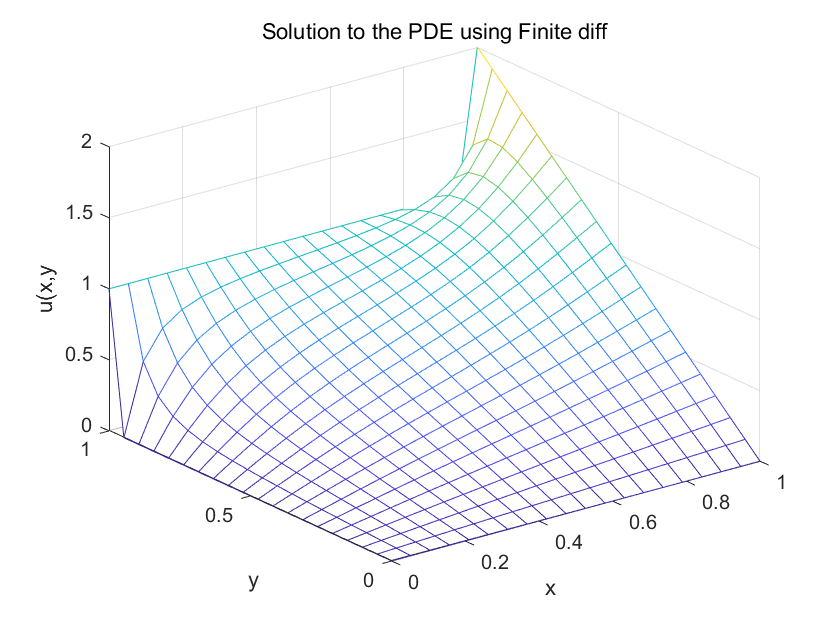

[uk]=FD(numPts,numPts,u_sol);
%plot
mesh(xx,yy,uk)
xlabel('x'); ylabel('y');zlabel('u(x,y')
title(['Solution to the PDE using Finite diff'])

From both plot above, we could see that the shape of these two plots are almost same, Finite difference method will give us more smooth curve.

By accutual compute the difference between these two method

Total_diff = sum(u-uk,'all')

ans = 0.0579

Total_abs_diff=sum(abs(u-uk),'all')

ans = 10.9501

function [uk] = FD(nx, ny, u)
%function of processing finite difference
%set k
    k = [0 -1 0;
        -1 4 -1;
        0 -1 0];
    V = [];
    b = [];
%step 1 loop from (2,2) to (nx-1),(ny-1)
    for j = 2:ny - 1
        for l = 2:nx - 1
            %step 2 set all 0 matrix 
            ut = zeros(ny, nx);
            %step 2 change the points around to k
            ut(j - 1:j + 1, l - 1:l + 1) = k;
            %step 3 cut the matrix from (2,2) to (nx-1),(ny-1)
            uc = ut(2:nx - 1, 2:ny - 1);
            %step 4 flat the cut matrix to 1 row and store it to V
            V = [V;reshape(uc', 1, (nx - 2)*(ny - 2))];
            %step 5 calculate b by adding the around point from IC matrix
            %together
            b = [b;u(j + 1, l) + u(j, l - 1) + u(j - 1, l) + u(j, l + 1)];
        end
    end
    uin = V\b;%step 6 calculate the result.
    u(2:nx - 1, 2:ny - 1) = reshape(uin, (nx - 2), (ny - 2))';
    %put the solution back into IC matrix.
    uk = u;
end